clear all;close all;format compact;
tau=20;%%control time 
para=[1.68 0.072 0.72 0.9 0.05 0.05 0.05]; %%[K1 K2 K3 p1i p2i p1f p2f] k21,k31,k32,pi(1),pi(2),pf(1),pf(2);  r1=p2/p1,r2=p1/(1-(p1+p2)).
[problem,guess]=corepressor(tau,para);          % Fetch the problem definition
    options= problem.settings(100);                 % Get options and solver settings 
    [solution,MRHistory]=solveMyProblem( problem,guess,options);

Determine sparsity structure
Formatting matrices for the hermite-simpson approximation
Generate finite-difference pertubation vectors

******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

This is Ipopt version 3.14.4, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:     5132
Number of nonzeros in Lagrangian Hessian.............:    10361

Total number of variables............................:      991
                     variables with only lower bounds:      597
                variables with lower and upper bounds:      394
                     va

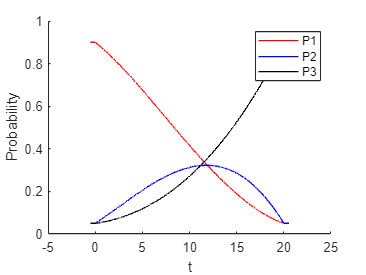

%% figures
xm=linspace(solution.T(1,1),solution.tf,10000)';
dxm=xm(2)-xm(1);

xi = linspace(-0.5,0,10)';
dxi = xi(2)-xi(1);
K12i = problem.data.ki(1)+zeros(10,1);
K21i = problem.data.ki(2)+zeros(10,1);
K13i = problem.data.ki(3)+zeros(10,1);
K31i = problem.data.ki(4)+zeros(10,1);
K23i = problem.data.ki(5)+zeros(10,1);
K32i = problem.data.ki(6)+zeros(10,1);
P1i = para(4)+zeros(10,1);
P2i = para(5)+zeros(10,1);
P3i = 1-(P1i+P2i);

K12m = speval(solution,'U',1,xm);
K21m = problem.data.ki(2)+zeros(length(K12m),1);
K13m = speval(solution,'U',2,xm);
K31m = problem.data.ki(4)+zeros(length(K12m),1);
K23m = speval(solution,'U',3,xm);
K32m = problem.data.ki(6)+zeros(length(K12m),1);

P1m=speval(solution,'X',1,xm);
P2m=speval(solution,'X',2,xm);
P3m=1-(speval(solution,'X',2,xm)+speval(solution,'X',1,xm));

k = para(1) + para(2)*para(3)/(para(2)+para(3));
Pf = [P1m(end),P2m(end)];
[P1f,P2f,P3f]=Terminal(Pf,problem.data.kf(1),problem.data.kf(2),problem.data.kf(3),problem.data.kf(4),problem.data.kf(5),problem.data.kf(6),0.001,k);
L = length(P1f);
K12f = problem.data.kf(1)+zeros(L,1);
K21f = problem.data.kf(2)+zeros(L,1);
K13f = problem.data.kf(3)+zeros(L,1);
K31f = problem.data.kf(4)+zeros(L,1);
K23f = problem.data.kf(5)+zeros(L,1);
K32f = problem.data.kf(6)+zeros(L,1);
xf = linspace(tau,tau+0.001*(L-1),L)';
dxf = xf(2)-xf(1);


dJ12i=dxi.*(P1i.*K12i-P2i.*K21i);
dJ13i=dxi.*(P1i.*K13i-P3i.*K31i);
dJ32i=dxi.*(P3i.*K32i-P2i.*K23i);
dJ12m=dxm.*(P1m.*K12m-P2m.*K21m);
dJ13m=dxm.*(P1m.*K13m-P3m.*K31m);
dJ32m=dxm.*(P3m.*K32m-P2m.*K23m);
dJ12f=dxf.*(P1f.*K12f-P2f.*K21f);
dJ13f=dxf.*(P1f.*K13f-P3f.*K31f);
dJ32f=dxf.*(P3f.*K32f-P2f.*K23f);



xx = cat(1,xi,xm,xf);
P1 = cat(1,P1i,P1m,P1f);
P2 = cat(1,P2i,P2m,P2f);
P3 = 1-(P1+P2);
K12 = cat(1,K12i,K12m,K12f);
K21 = cat(1,K21i,K21m,K21f);
K13 = cat(1,K13i,K13m,K13f);
K31 = cat(1,K31i,K31m,K31f);
K23 = cat(1,K23i,K23m,K23f);
K32 = cat(1,K32i,K32m,K32f);
dJ12 = cat(1,dJ12i,dJ12m,dJ12f);
dJ13 = cat(1,dJ13i,dJ13m,dJ13f);
dJ32 = cat(1,dJ32i,dJ32m,dJ32f);

J12=integra(dJ12);
J13=integra(dJ13);
J32=integra(dJ32);
R12=K12./K21;
R13=K13./K31;
R32=K32./K23;
r12=P2./P1;
r13=P3./P1;
r32=P2./P3;
C12 = (P1.*K12-P2.*K21).*log((P1.*K12)./(P2.*K21));
C13 = (P1.*K13-P3.*K31).*log((P1.*K13)./(P3.*K31));
C32 = (P3.*K32-P2.*K23).*log((P3.*K32)./(P2.*K23));
CCost = C12 + C13 + C32;



linewidh = 0.1;
figure
hold on
plot(xx,P1,'r' ,'LineWidth',linewidh)
plot(xx,P2,'b' ,'LineWidth',linewidh)
plot(xx,P3,'k' ,'LineWidth',linewidh)
xlabel('t')
ylabel('Probability')
legend('P1','P2','P3')

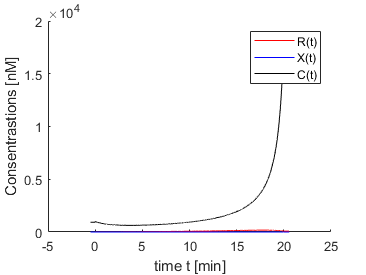


figure
hold on
r12=K12./0.0191;
r13=K13./0.9;
r32=K23./(7.83*0.0001);
p1plt = plot(xx(1:length(xi)),r12(1:length(xi)),'r','LineWidth',linewidh);
plot(xx(length(xi):length(xi)+2),r12(length(xi):length(xi)+2),'r','LineWidth',linewidh,'LineStyle','-.');
plot(xx(1+length(xi):length(xi)+length(xm)),r12(1+length(xi):length(xi)+length(xm)),'r','LineWidth',linewidh);
plot(xx(length(xi)+length(xm):length(xi)+length(xm)+2),r12(length(xi)+length(xm):length(xi)+length(xm)+2),'r','LineWidth',linewidh,'LineStyle','-.');
plot(xx(1+length(xm)+length(xi):end),r12(1+length(xm)+length(xi):end),'r','LineWidth',linewidh);

p2plt = plot(xx(1:length(xi)),r13(1:length(xi)),'b','LineWidth',linewidh);
plot(xx(length(xi):length(xi)+2),r13(length(xi):length(xi)+2),'b','LineWidth',linewidh,'LineStyle','-.');
plot(xx(1+length(xi):length(xi)+length(xm)),r13(1+length(xi):length(xi)+length(xm)),'b','LineWidth',linewidh);
plot(xx(length(xi)+length(xm):length(xi)+length(xm)+2),r13(length(xi)+length(xm):length(xi)+length(xm)+2),'b','LineWidth',linewidh,'LineStyle','-.');
plot(xx(1+length(xm)+length(xi):end),r13(1+length(xm)+length(xi):end),'b','LineWidth',linewidh);

p3plt = plot(xx(1:length(xi)),r32(1:length(xi)),'k','LineWidth',linewidh);
plot(xx(length(xi):length(xi)+2),r32(length(xi):length(xi)+2),'k','LineWidth',linewidh,'LineStyle','-.');
plot(xx(1+length(xi):length(xi)+length(xm)),r32(1+length(xi):length(xi)+length(xm)),'k','LineWidth',linewidh);
plot(xx(length(xi)+length(xm):length(xi)+length(xm)+2),r32(length(xi)+length(xm):length(xi)+length(xm)+2),'k','LineWidth',linewidh,'LineStyle','-.');
plot(xx(1+length(xm)+length(xi):end),r32(1+length(xm)+length(xi):end),'k','LineWidth',linewidh);

xlabel('time t [min]')
ylabel('Consentrastions [nM]')
legend([p1plt,p2plt,p3plt],'R(t)','X(t)','C(t)')

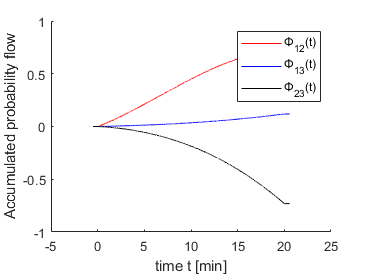


figure
hold on
plot(xx,J12,'r','LineWidth',linewidh)
plot(xx,J13,'b','LineWidth',linewidh)
plot(xx,J32,'k','LineWidth',linewidh)
xlabel('time t [min]')
ylabel('Accumulated probability flow')
legend('Φ_{12}(t)','Φ_{13}(t)','Φ_{23}(t)')